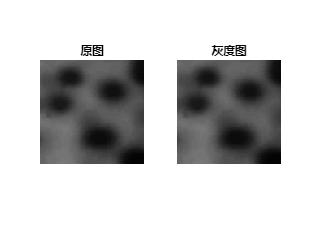

 %分水岭算法自己的实现

clc;
clear;
close all;


%读入原图像
img = imread('E:\Books\书本完整图片库\DIP3E_Original_Images_CH10\Fig1056(a)(blob_original).tif');

%ndims()获取图像维数（通道数）
if ndims(img) == 3
    %转换为灰度图
    gray = rgb2gray(img);

else
    gray = img;

end

subplot(1,2,1); imshow(img); title('原图');

subplot(1,2,2); imshow(gray); title('灰度图');

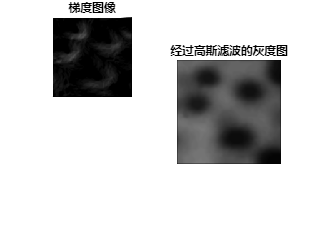

%计算梯度前，使用高斯滤波器增强图像
filtergauss = fspecial('gaussian',[3 3],10);
gray = imfilter(gray,filtergauss);

figure;
subplot(1, 2, 2); imshow(gray); title('经过高斯滤波的灰度图');



%Sobel算子计算梯度图像，gradientimgy为横向梯度，gradientimgx为纵向梯度
%

gradientimgy = imfilter(gray,[-1,0,1;-2,0,2;-1,0,1]);

gradientimgx = imfilter(gray,[-1,-2,-1;0,0,0;1,2,1]);

gradientimg = abs(gradientimgx) + abs(gradientimgy);

%对梯度图像再次使用高斯滤波器
%imfilter(gradientimg,filtergauss);

%对二值梯度图像使用开操作
%edge = imopen(imbinarize(round(edge),'adaptive'),[1,1,1;1,1,1;1,1,1]);

subplot(2, 2, 1);
imshow(gradientimg);
title('梯度图像');

minimum = min(min(gray));
maximum = max(max(gray));

%标记图像,-1表示未标记，0表示边缘
marker = -1*ones(size(gradientimg));
marker(gradientimg ~= 0) = 0;

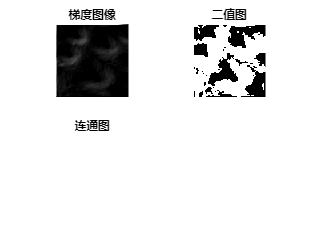

%开始分水岭算法
%threshold -- 水平面当前值，从minimum开始增长到maximum
%让梯度图像上小于threshold的像素点在梯度图上置为minimum，此为当前水平面
%然后二值化

threshold = minimum;
%edge(edge < threshold) = minimum;
%二值化
binary = imbinarize(int8(gradientimg),threshold/maximum);
subplot(2, 2, 2);
imshow(binary);

%marker=0表示边缘
marker(binary~=0) = 0;
title('二值图');

%开始注水
gradientimg(gradientimg <= threshold)=threshold + 1;
    
%二值化
binary = imbinarize(int8(gradientimg),threshold/maximum);

%提取连通分量
[connected_area,~,~] = substract_connected_area(binary);
connected_area = gradientimg(connected_area);
subplot(2, 2, 3);
imshow(connected_area);
title('连通图');


threshold = threshold+1;


 
gradientimg(gradientimg < threshold)=threshold + 1;
    
%二值化 
binary = imbinarize(int8(gradientimg),threshold/maximum); 
threshold = threshold+1;
    
%提取连通分量
[connected_area,marker,number_of_connected] = substract_connected_area(binary);

subplot(2, 2, 3);

imshow(gradientimg(connected_area));
title('连通图');



Index in position 1 is invalid. Array indices must be positive integers or logical values.

Error in watershed_algorithm_by_myself>substract_connected_area (line 140)
connected_area(start_row,start_col) = 1;

%连通分量提取 connected_area = substract_connected_area(edgebinary);


%找出二值图中的一个连通集

function [connected_area,marker,number_of_connected] = substract_connected_area(bwimg)
%bwimg --- 二值图
%connected_area --- 
eight_connect_template = [1,1,1;
                          1,1,1;
                          1,1,1];

[row,col] = size(bwimg); 
connected_area = zeros(row,col);
marker = -1 * ones(size(bwimg));

%total_maker_number -- 已经使用的标记数目
total_maker_number = 0;

start_row = 0;
start_col = 0;

%找出二值图中第一个非0位置 
for ii = 1:row
    for jj = 1:col
        if bwimg(ii,jj) == 1 
            start_row = ii;
            start_col = jj;
            break;
        end
    end
    
end

connected_area(start_row,start_col) = 1;

while 1 
    %膨胀 
    dilatedimg = imdilate(connected_area,eight_connect_template);

    %and operation与操作
    connected_area = immultiply(dilatedimg , bwimg);

    if immultiply(imdilate(connected_area,eight_connect_template) , bwimg) == connected_area 
        break; 
    end 
end

number_of_connected = 1;
end
